Create a 3-dimensional data set consisting of 5 Gaussian classes and all of the classes retain significant overlaps within one or two standard deviations of their means. We ensure the Mahalanobis distance is between 1 or 2 by measuring the distance of every data point to the mean of the previous class and randomly pick one in those data points that have distance between 1 or 2. See  create_cov() and create_mean() functions for more details.

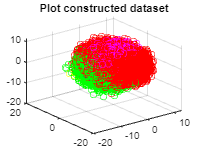

% create mean, covariance and data
class1_sigma = create_cov(12, 29, 15, [9 8 5]);
class1_mu = [0 0 0];
class1_data = Gaussian_whitening(3,750000, class1_mu, class1_sigma);
class1_labels = ones(750000,1);

class2_sigma = create_cov(21, 28, 22, [2 1 1]);
class2_mu = create_mean(class1_data, class1_mu, class1_sigma);
class2_data = Gaussian_whitening(3,190000, class2_mu, class2_sigma);
class2_labels = ones(190000,1)*2;

class3_sigma = create_cov(33, 36, 34, [10 5 5]);
class3_mu = create_mean(class2_data, class2_mu, class2_sigma);
class3_data = Gaussian_whitening(3,45000, class3_mu, class3_sigma);
class3_labels = ones(45000,1)*3;

class4_sigma = create_cov(45, 47, 41, [9 5 7]);
class4_mu = create_mean(class3_data, class3_mu, class3_sigma);
class4_data = Gaussian_whitening(3,12000, class4_mu, class4_sigma);
class4_labels = ones(12000,1)*4;

class5_sigma = create_cov(56, 50, 59, [3 6 9]);
class5_mu = create_mean(class4_data, class4_mu, class4_sigma);
class5_data = Gaussian_whitening(3,3000, class5_mu, class5_sigma);
class5_labels = ones(3000,1)*5;

%plot
scatter3(class1_data(:,1),class1_data(:,2),class1_data(:,3),'red');
hold on
scatter3(class2_data(:,1),class2_data(:,2),class2_data(:,3), 'blue');
scatter3(class3_data(:,1),class3_data(:,2),class3_data(:,3), 'green');
scatter3(class4_data(:,1),class4_data(:,2),class4_data(:,3), 'magenta');
scatter3(class5_data(:,1),class5_data(:,2),class5_data(:,3), 'yellow');
title('Plot constructed dataset');
hold off

Construct randomly (uniformly) selected training and test data set from the composite of your constructed 5 class data sets, where the training data should constitute 10% of the overall data and the test data the remaining 90% of the data. Record the number of train data samples for each of the training set classes as well as the exact indexes of the training and test data samples.

dataset = [class1_data; class2_data; class3_data; class4_data; class5_data];
labels = [class1_labels; class2_labels; class3_labels; class4_labels; class5_labels];

%{
% shuffle dataset first
rand_idx = randperm(1000000);
shuffled_data = dataset(rand_idx,:);
shuffled_labels = labels(rand_idx,:);
%}

% train test split
[train_set, test_set, train_labels, test_labels] = train_test_split(0.1, dataset, labels);
disp(size(train_set));

      100000           3



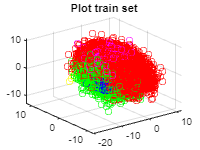


% find indices of each class both train and test
class1_trainIdx = find(train_labels==1);
class2_trainIdx = find(train_labels==2);
class3_trainIdx = find(train_labels==3);
class4_trainIdx = find(train_labels==4);
class5_trainIdx = find(train_labels==5);

% plot
scatter3(train_set(class1_trainIdx,1),train_set(class1_trainIdx,2),train_set(class1_trainIdx,3),'red');
hold on
scatter3(train_set(class2_trainIdx,1),train_set(class2_trainIdx,2),train_set(class2_trainIdx,3), 'blue');
scatter3(train_set(class3_trainIdx,1),train_set(class3_trainIdx,2),train_set(class3_trainIdx,3), 'green');
scatter3(train_set(class4_trainIdx,1),train_set(class4_trainIdx,2),train_set(class4_trainIdx,3), 'magenta');
scatter3(train_set(class5_trainIdx,1),train_set(class5_trainIdx,2),train_set(class5_trainIdx,3), 'yellow');
title('Plot train set');
hold off


class1_testIdx = find(test_labels==1);
class2_testIdx = find(test_labels==2);
class3_testIdx = find(test_labels==3);
class4_testIdx = find(test_labels==4);
class5_testIdx = find(test_labels==5);

% find data for each class in train dataset
class1_train = train_set(class1_trainIdx,:);
class2_train = train_set(class2_trainIdx,:);
class3_train = train_set(class3_trainIdx,:);
class4_train = train_set(class4_trainIdx,:);
class5_train = train_set(class5_trainIdx,:);

% find test data for each class in train dataset
class1_test = test_set(class1_testIdx,:);
class2_test = test_set(class2_testIdx,:);
class3_test = test_set(class3_testIdx,:);
class4_test = test_set(class4_testIdx,:);
class5_test = test_set(class5_testIdx,:);

Question 3

Use the training data sets to build and a Bayes and neural network classifier for this data

% Bayes
% calculate probability of each class
num_train = length(train_set);
num_class1 = sum(train_labels(:) == 1);
num_class2 = sum(train_labels(:) == 2);
num_class3 = sum(train_labels(:) == 3);
num_class4 = sum(train_labels(:) == 4);
num_class5 = sum(train_labels(:) == 5);

prob_class1 = num_class1/num_train;
prob_class2 = num_class2/num_train;
prob_class3 = num_class3/num_train;
prob_class4 = num_class4/num_train;
prob_class5 = num_class5/num_train;

% calculate mean and covariance of each class
train_class1_mu = mean(class1_train);
train_class2_mu = mean(class2_train);
train_class3_mu = mean(class3_train);
train_class4_mu = mean(class4_train);
train_class5_mu = mean(class5_train);

train_class1_cov = cov(class1_train);
train_class2_cov = cov(class2_train);
train_class3_cov = cov(class3_train);
train_class4_cov = cov(class4_train);
train_class5_cov = cov(class5_train);

%Neural Nets
% declare a neural network
net = patternnet;
net.trainParam.showWindow = false;
% initialize the network weights
net = init(net);
[net,tr] = train(net,train_set' ,onehotencode(categorical(train_labels'),1));

Apply the testing data to assess the per-class performance of your constructed classifiers. To assess performance of Neural nets and Bayes on unbalanced dataset. We listed number of data points correclty classified per class and accuracy per class relative to true labels.

% Bayes performance
% create discriminant function
g1 = Discriminant(test_set, train_class1_mu', train_class1_cov, prob_class1);
g2 = Discriminant(test_set, train_class2_mu', train_class2_cov, prob_class2);
g3 = Discriminant(test_set, train_class3_mu', train_class3_cov, prob_class3);
g4 = Discriminant(test_set, train_class4_mu', train_class4_cov, prob_class4);
g5 = Discriminant(test_set, train_class5_mu', train_class5_cov, prob_class5);

% predict and then compare with true test labels
%Pred_class1 = find(g1>max(cat(1,g2,g3,g4,g5)));
%Pred_class2 = find(g2>max(cat(1,g1,g3,g4,g5)));
%Pred_class3 = find(g3>max(cat(1,g1,g2,g4,g5)));
%Pred_class4 = find(g4>max(cat(1,g1,g2,g3,g5)));
%Pred_class5 = find(g5>max(cat(1,g1,g2,g3,g4)));

Pred_class1 = find(g1>max(max(max(g2,g3),g4),g5));
Pred_class2 = find(g2>max(max(max(g1,g3),g4),g5));
Pred_class3 = find(g3>max(max(max(g1,g2),g4),g5));
Pred_class4 = find(g4>max(max(max(g1,g2),g3),g5));
Pred_class5 = find(g5>max(max(max(g1,g2),g3),g4));

% compare predictions and true labels
diff1_idx = ismember(Pred_class1,class1_testIdx);
diff2_idx = ismember(Pred_class2,class2_testIdx);
diff3_idx = ismember(Pred_class3,class3_testIdx);
diff4_idx = ismember(Pred_class4,class4_testIdx);
diff5_idx = ismember(Pred_class5,class5_testIdx);

Bayes_corrects = [sum(diff1_idx);sum(diff2_idx);sum(diff3_idx);...
    sum(diff4_idx);sum(diff5_idx)];
disp('Number of predictions of Bayes correctly classified for each class (from class 1 to 5)');

Number of predictions of Bayes correctly classified for each class (from class 1 to 5)


disp(Bayes_corrects);

      653169
      159230
        6988
           2
          19




Bayes_acc_class = [sum(diff1_idx)/length(class1_testIdx)...
    ;sum(diff2_idx)/length(class2_testIdx)...
    ;sum(diff3_idx)/length(class3_testIdx)...
    ;sum(diff4_idx)/length(class4_testIdx)...
    ;sum(diff5_idx)/length(class5_testIdx)];
disp('Percentage of Bayes correctly classified for each class (from class 1 to 5)');

Percentage of Bayes correctly classified for each class (from class 1 to 5)


disp(Bayes_acc_class);

    0.9679
    0.9305
    0.1723
    0.0002
    0.0070




% calculate accuracy 
acc = (length(find(diff1_idx))...
    +length(find(diff2_idx))...
    +length(find(diff3_idx))...
    +length(find(diff4_idx))...
    +length(find(diff5_idx)))/length(test_set);
disp('Bayes overall accuracy');

Bayes overall accuracy


disp(acc);

    0.9105




% Neural Nets performance
pred_net = net(test_set');

% compare predictions
pred_net = vec2ind(pred_net);

net_diff1_idx = ismember(find(pred_net==1),class1_testIdx);
net_diff2_idx = ismember(find(pred_net==2),class2_testIdx);
net_diff3_idx = ismember(find(pred_net==3),class3_testIdx);
net_diff4_idx = ismember(find(pred_net==4),class4_testIdx);
net_diff5_idx = ismember(find(pred_net==5),class5_testIdx);

net_corrects = [sum(net_diff1_idx);...
    sum(net_diff2_idx);...
    sum(net_diff3_idx);...
    sum(net_diff4_idx);...
    sum(net_diff5_idx)];
disp('Number of predictions of Neural Nets correctly classified for each class (from class 1 to 5)');

Number of predictions of Neural Nets correctly classified for each class (from class 1 to 5)


disp(net_corrects);

      653668
      159045
        6288
           7
           0




net_acc_class = [sum(net_diff1_idx)/length(class1_testIdx);...
    sum(net_diff2_idx)/length(class2_testIdx);...
    sum(net_diff3_idx)/length(class3_testIdx);...
    sum(net_diff4_idx)/length(class4_testIdx);...
    sum(net_diff5_idx)/length(class5_testIdx)];
disp('Percentage of Neural Nets correctly classified for each class (from class 1 to 5)');

Percentage of Neural Nets correctly classified for each class (from class 1 to 5)


disp(net_acc_class);

    0.9686
    0.9294
    0.1551
    0.0006
         0




% calculate accuracy
net_acc = (sum(net_diff1_idx)+sum(net_diff2_idx)+sum(net_diff3_idx)...
    +sum(net_diff4_idx)+sum(net_diff5_idx))/length(test_set);
disp('Neural Nets overall accuracy');

Neural Nets overall accuracy


disp(net_acc);

    0.9100



Parametric apporaches follow a specfic parametric form which, in this case, is gaussian distribution and the probability density function has fixed functional form which is determined by parameters (means and covariances). Comparatively, non-parametric approaches also need parameters but those parameters are not fixed, such that Neural Nets can take countless number of combinations of different parameters. As we can observe from the assessments, both Neural nets and Bayes are not robust and both sensitive to unbalanced data sets. Both classifiers are very accurate in classes (1,2) that have dominating number of data points. Performance on class 3, 4 and 5 is bad, as they occupy very small proportion of the dataset. However, the reasons on why bad performance on class 3, 4 and 5 are different for Neural Nets and Bayes. Bayes had bad performance becuase all of the classes overlap with each other within one or two standard deviations, so means and covariances are not providing useful information for Bayes to classify data points. To minimize risks, Bayes will extensively choose class 1 and 2. Neural Nets had bad performance because number of data points available for 3, 4 and 5 are too small to let Neural Nets learn and get enough information for correct predictions.

As we can observe from the performance of balanced dataset, the per-class performance on class 3, 4 and 5 significantly improved. However, the overall performance significantly reduced for both classifiers due to huge reduction in number of training data.

% train test split
[train_set, test_set, train_labels, test_labels] = stratified_split(class1_data,class2_data,...
    class3_data,class4_data,class5_data,class1_labels, class2_labels, class3_labels,...
    class4_labels, class5_labels, 0.1, 3000);
disp(size(train_set));

        1500           3



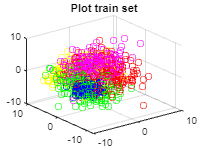


% find indices of each class both train and test
class1_trainIdx = find(train_labels==1);
class2_trainIdx = find(train_labels==2);
class3_trainIdx = find(train_labels==3);
class4_trainIdx = find(train_labels==4);
class5_trainIdx = find(train_labels==5);

% plot
scatter3(train_set(class1_trainIdx,1),train_set(class1_trainIdx,2),train_set(class1_trainIdx,3),'red');
hold on
scatter3(train_set(class2_trainIdx,1),train_set(class2_trainIdx,2),train_set(class2_trainIdx,3), 'blue');
scatter3(train_set(class3_trainIdx,1),train_set(class3_trainIdx,2),train_set(class3_trainIdx,3), 'green');
scatter3(train_set(class4_trainIdx,1),train_set(class4_trainIdx,2),train_set(class4_trainIdx,3), 'magenta');
scatter3(train_set(class5_trainIdx,1),train_set(class5_trainIdx,2),train_set(class5_trainIdx,3), 'yellow');
title('Plot train set');
hold off


class1_testIdx = find(test_labels==1);
class2_testIdx = find(test_labels==2);
class3_testIdx = find(test_labels==3);
class4_testIdx = find(test_labels==4);
class5_testIdx = find(test_labels==5);

% find data for each class in train dataset
class1_train = train_set(class1_trainIdx,:);
class2_train = train_set(class2_trainIdx,:);
class3_train = train_set(class3_trainIdx,:);
class4_train = train_set(class4_trainIdx,:);
class5_train = train_set(class5_trainIdx,:);

% find test data for each class in train dataset
class1_test = test_set(class1_testIdx,:);
class2_test = test_set(class2_testIdx,:);
class3_test = test_set(class3_testIdx,:);
class4_test = test_set(class4_testIdx,:);
class5_test = test_set(class5_testIdx,:);

% Bayes
% calculate probability of each class
num_train = length(train_set);
num_class1 = sum(train_labels(:) == 1);
num_class2 = sum(train_labels(:) == 2);
num_class3 = sum(train_labels(:) == 3);
num_class4 = sum(train_labels(:) == 4);
num_class5 = sum(train_labels(:) == 5);

prob_class1 = num_class1/num_train;
prob_class2 = num_class2/num_train;
prob_class3 = num_class3/num_train;
prob_class4 = num_class4/num_train;
prob_class5 = num_class5/num_train;

% calculate mean and covariance of each class
train_class1_mu = mean(class1_train);
train_class2_mu = mean(class2_train);
train_class3_mu = mean(class3_train);
train_class4_mu = mean(class4_train);
train_class5_mu = mean(class5_train);

train_class1_cov = cov(class1_train);
train_class2_cov = cov(class2_train);
train_class3_cov = cov(class3_train);
train_class4_cov = cov(class4_train);
train_class5_cov = cov(class5_train);

%Neural Nets
% declare a neural network
net = patternnet;
net.trainParam.showWindow = false;
% initialize the network weights
net = init(net);
[net,tr] = train(net,train_set' ,onehotencode(categorical(train_labels'),1));

% Bayes performance
% create discriminant function
g1 = Discriminant(test_set, train_class1_mu', train_class1_cov, prob_class1);
g2 = Discriminant(test_set, train_class2_mu', train_class2_cov, prob_class2);
g3 = Discriminant(test_set, train_class3_mu', train_class3_cov, prob_class3);
g4 = Discriminant(test_set, train_class4_mu', train_class4_cov, prob_class4);
g5 = Discriminant(test_set, train_class5_mu', train_class5_cov, prob_class5);

% predict and then compare with true test labels
%Pred_class1 = find(g1>max(cat(1,g2,g3,g4,g5)));
%Pred_class2 = find(g2>max(cat(1,g1,g3,g4,g5)));
%Pred_class3 = find(g3>max(cat(1,g1,g2,g4,g5)));
%Pred_class4 = find(g4>max(cat(1,g1,g2,g3,g5)));
%Pred_class5 = find(g5>max(cat(1,g1,g2,g3,g4)));

Pred_class1 = find(g1>max(max(max(g2,g3),g4),g5));
Pred_class2 = find(g2>max(max(max(g1,g3),g4),g5));
Pred_class3 = find(g3>max(max(max(g1,g2),g4),g5));
Pred_class4 = find(g4>max(max(max(g1,g2),g3),g5));
Pred_class5 = find(g5>max(max(max(g1,g2),g3),g4));

% compare predictions and true labels
diff1_idx = ismember(Pred_class1,class1_testIdx);
diff2_idx = ismember(Pred_class2,class2_testIdx);
diff3_idx = ismember(Pred_class3,class3_testIdx);
diff4_idx = ismember(Pred_class4,class4_testIdx);
diff5_idx = ismember(Pred_class5,class5_testIdx);

Bayes_corrects = [sum(diff1_idx);sum(diff2_idx);sum(diff3_idx);...
    sum(diff4_idx);sum(diff5_idx)];
disp('Balanced dataset: Number of predictions of Bayes correctly classified for each class (from class 1 to 5)');

Balanced dataset: Number of predictions of Bayes correctly classified for each class (from class 1 to 5)


disp(Bayes_corrects);

        1266
        2453
        1481
        1539
        1658




Bayes_acc_class = [sum(diff1_idx)/length(class1_testIdx)...
    ;sum(diff2_idx)/length(class2_testIdx)...
    ;sum(diff3_idx)/length(class3_testIdx)...
    ;sum(diff4_idx)/length(class4_testIdx)...
    ;sum(diff5_idx)/length(class5_testIdx)];
disp('Balanced dataset: Percentage of Bayes correctly classified for each class (from class 1 to 5)');

Balanced dataset: Percentage of Bayes correctly classified for each class (from class 1 to 5)


disp(Bayes_acc_class);

    0.4689
    0.9085
    0.5485
    0.5700
    0.6141




% calculate accuracy 
acc = (length(find(diff1_idx))...
    +length(find(diff2_idx))...
    +length(find(diff3_idx))...
    +length(find(diff4_idx))...
    +length(find(diff5_idx)))/length(test_set);
disp('Balanced dataset: Bayes overall accuracy');

Balanced dataset: Bayes overall accuracy


disp(acc);

    0.6220




% Neural Nets performance
pred_net = net(test_set');

% compare predictions
pred_net = vec2ind(pred_net);

net_diff1_idx = ismember(find(pred_net==1),class1_testIdx);
net_diff2_idx = ismember(find(pred_net==2),class2_testIdx);
net_diff3_idx = ismember(find(pred_net==3),class3_testIdx);
net_diff4_idx = ismember(find(pred_net==4),class4_testIdx);
net_diff5_idx = ismember(find(pred_net==5),class5_testIdx);

net_corrects = [sum(net_diff1_idx);...
    sum(net_diff2_idx);...
    sum(net_diff3_idx);...
    sum(net_diff4_idx);...
    sum(net_diff5_idx)];
disp('Balanced dataset: Number of predictions of Neural Nets correctly classified for each class (from class 1 to 5)');

Balanced dataset: Number of predictions of Neural Nets correctly classified for each class (from class 1 to 5)


disp(net_corrects);

        1261
        2451
        1300
        1640
        1450




net_acc_class = [sum(net_diff1_idx)/length(class1_testIdx);...
    sum(net_diff2_idx)/length(class2_testIdx);...
    sum(net_diff3_idx)/length(class3_testIdx);...
    sum(net_diff4_idx)/length(class4_testIdx);...
    sum(net_diff5_idx)/length(class5_testIdx)];
disp('Balanced dataset: Percentage of Neural Nets correctly classified for each class (from class 1 to 5)');

Balanced dataset: Percentage of Neural Nets correctly classified for each class (from class 1 to 5)


disp(net_acc_class);

    0.4670
    0.9078
    0.4815
    0.6074
    0.5370




% calculate accuracy
net_acc = (sum(net_diff1_idx)+sum(net_diff2_idx)+sum(net_diff3_idx)...
    +sum(net_diff4_idx)+sum(net_diff5_idx))/length(test_set);
disp('Balanced dataset: Neural Nets overall accuracy');

Balanced dataset: Neural Nets overall accuracy


disp(net_acc);

    0.6001



Functions

% function for accurate dataset

function x = Gaussian_whitening(D,K, mu, sigma)
    data = randn(K,D);
    % singular decomposition of covariance
    [u,s,v] = svd(sigma);
    s = sqrt(s);
    % only use left or right singular vectors
    % use left here to create correlations
    data_correlated = data*s*u' + mu;
    m = mean(data_correlated); % mean of data generated with specified mean
    c = cov(data_correlated); %covarinace of data generated with specified covarinace

    % subtracting mean
    x = data_correlated - m;

    % Whitening transformation
    % Peform eigenvalue/eigenvector decomposition
    [v,d] = eig(c);
    [ d_sorted , idx_sorted ] = sort( diag( d ) , 'descend' );
    w = v(:, idx_sorted);
    x = x * w * diag(1./sqrt(d_sorted));
    x = x*s*u' + mu;
end

% create covariance matrix: V = Rv*Ry*Rz, cov = V*D*inv(V)
function cv = create_cov(theta, phi, psi, d)
    Rx = [1 0 0;0 cosd(theta) -sind(theta);0 sind(theta) cosd(theta)];
    Ry = [cosd(phi) 0 sind(phi);0 1 0;-sind(phi) 0 cosd(phi)];
    Rz = [cos(psi) -sin(psi) 0;sin(psi) cos(psi) 0;0 0 1];
    V = Rx*Ry*Rz;
    D = [d(1) 0 0;0 d(2) 0;0 0 d(3)];
    cv = V*D*inv(V);
end

% find overlap mean
function overlap_mean = create_mean(DA, mu, cov)
    distances = zeros(length(DA),1);
    % find Mahalanobis distance between 1 to 2
    for i = 1:length(DA)
        x = DA(i,:);
        d = (x-mu)*inv(cov)*(x-mu)';
        distances(i) = d;
    end
    one_indices = find(distances>=1 | distances<=2);
    % return the random data point as mean
    rand_num = randi(max(one_indices));
    overlap_mean = DA(rand_num,:);
end

% train test split functions
function [train, test, train_y, test_y]=train_test_split(ratio, dataset, y)
    s = size(dataset);
    m = s(1);
    % generate random indices
    rand_idx = randperm(m);
    train_idx = rand_idx(1:round(ratio*m));
    test_idx = rand_idx(round(ratio*m)+1:end);
    % generate train and test given random indices
    train = dataset(train_idx,:);
    test = dataset(test_idx,:);
    train_y = y(train_idx);
    test_y = y(test_idx);
end

% function for discriminant analysis
function gi = Discriminant(x, mu, sigma, prob)
    % caluclate terms for discriminat function separatly
    inv_sigma = inv(sigma);
    cap_w = -1/2*inv_sigma;
    w = inv_sigma*mu;
    w_const = -1/2*(mu.')*inv_sigma*mu - 1/2*log(det(sigma)) + log(prob);
    
    % create discriminant function
    gi = dot((x*cap_w).',x.') + (w.')*x.' + w_const;
end

% stratified split functions
function [train, test, train_y, test_y]=stratified_split(c1,c2,c3,c4,c5, y1, y2, y3, y4, y5, ratio, m)
    % generate random indices
    rand_idx = randperm(m);
    train_idx = rand_idx(1:round(ratio*m));
    test_idx = rand_idx(round(ratio*m)+1:end);
    % equal split with each class
    c1_train = c1(train_idx,:);
    c1_test = c1(test_idx,:);
    c2_train = c2(train_idx,:);
    c2_test = c2(test_idx,:);
    c3_train = c3(train_idx,:);
    c3_test = c3(test_idx,:);
    c4_train = c4(train_idx,:);
    c4_test = c4(test_idx,:);
    c5_train = c5(train_idx,:);
    c5_test = c5(test_idx,:);
    train_y1 = y1(train_idx);
    test_y1 = y1(test_idx);
    train_y2 = y2(train_idx);
    test_y2 = y2(test_idx);
    train_y3 = y3(train_idx);
    test_y3 = y3(test_idx);
    train_y4 = y4(train_idx);
    test_y4 = y4(test_idx);
    train_y5 = y5(train_idx);
    test_y5 = y5(test_idx);
    train = [c1_train;c2_train;c3_train;c4_train;c5_train];
    test = [c1_test;c2_test;c3_test;c4_test;c5_test];
    train_y = [train_y1;train_y2;train_y3;train_y4;train_y5];
    test_y = [test_y1;test_y2;test_y3;test_y4;test_y5];
end